clc, clear

load('matlab.mat')

syms t time r 
assume(t,'real'); % parameter t should be real
assume(t,'positive');

ri = (0.3960*cos(2.65*(0.1*t+1.4)));
rj = (-0.99*sin(0.1*t+1.4));
rk = 0*t;
r = [ri,rj,rk];
drdt = diff(r,t);
linvel = norm(drdt)

$$linvel = \sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,t}{200}+\frac{371}{100}\right)\right|}^{2}}{2500000000}+\frac{9801\,{\left|\cos\left(\frac{t}{10}+\frac{7}{5}\right)\right|}^{2}}{1000000}}$$

%calculating unit tangent vector
T_hat = drdt/norm(drdt);
dT_hatdt = diff(T_hat,t);

%calculating angular velocity
angvel = cross(T_hat,dT_hatdt);
Angular_Velocity = angvel(3);

%turning vector components of t_hat into x and y functions (MATLAB)
t_hat_x = matlabFunction(T_hat(1));
t_hat_y = matlabFunction(T_hat(2));

%calculating unit normal vector
N_hat = dT_hatdt/norm(dT_hatdt);

%turning vector components of n_hat into x and y functions (MATLAB)
n_hat_x = matlabFunction(N_hat(1));
n_hat_y = matlabFunction(N_hat(2));

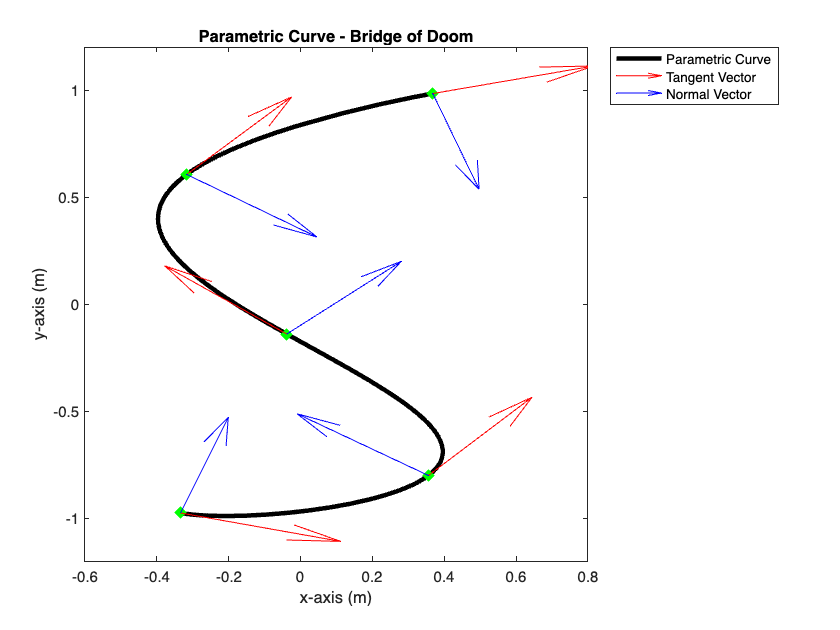

figure("Name","Parametric Curve")
bod_curve = fplot(ri,rj,[0 32],'-k','LineWidth',3);
hold on
T_hat_matlab = matlabFunction(T_hat);
ri_quiv = matlabFunction(ri);
rj_quiv = matlabFunction(rj);

%define time
t = 0:8:32;

%defines the functions in terms of x and y coordinates
x = ri_quiv(t);
y = rj_quiv(t);
u = t_hat_x(t);
v = t_hat_y(t);
i = n_hat_x(t);
o = n_hat_y(t);

%plotting unit and tangent vectors on bod curve
plot(x,y,'xg',LineWidth=6)
unit_tan_graph = quiver(x,y,u*0.25,v*0.25,'-r','LineWidth',0.1);
unit_norm_graph = quiver(x,y,i*0.25,o*0.25,'-b','LineWidth',0.1);
set(unit_tan_graph,'AutoScale','on', 'AutoScaleFactor',0.5)
set(unit_norm_graph,'AutoScale','on', 'AutoScaleFactor',0.5)
xlim([-0.6 0.8])
ylim([-1.2 1.2])
xlabel("x-axis (m)")
ylabel("y-axis (m)")
legend([bod_curve, unit_tan_graph,unit_norm_graph],["Parametric Curve", "Tangent Vector","Normal Vector"],'Location','northeastoutside')
title("Parametric Curve - Bridge of Doom")
hold off

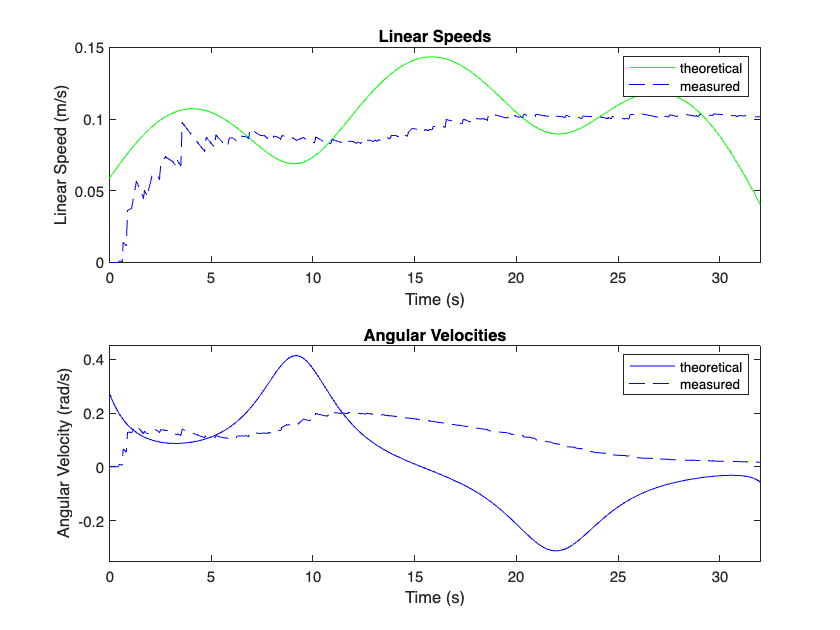

% measured left and right wheel velocities
simLeftWheelVel = encoder_data(:,2) ./ encoder_data(:,1);
simRightWheelVel = encoder_data(:,3) ./ encoder_data(:,1);

%calculate measured linear vel
simlinvel = (simLeftWheelVel + simRightWheelVel)/2;

% calculate measured angular vel
simangvel = (simlinvel - simLeftWheelVel) * (2/0.245);

% plot linear and angular velocities
figure("Name","Linear and Angular Velocities")

subplot(2,1,1);
linvelgraph = fplot(linvel,[0 32],'-g');
hold on;
actual_linvel = plot(encoder_data(:,1),simlinvel,'--b');
hold off;
ylim([0 0.15])
xlabel("Time (s)")
ylabel("Linear Speed (m/s)")
legend([linvelgraph, actual_linvel], ["theoretical", "measured"]);
title("Linear Speeds")

subplot(2,1,2);
angvelgraph = fplot(Angular_Velocity,[0 32],'-b');
hold on;
actual_angvel = plot(encoder_data(:,1),simangvel,'--b');
hold off;
ylim([-0.35 0.45]);
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend([angvelgraph, actual_angvel], ["theoretical", "measured"]);
title("Angular Velocities")

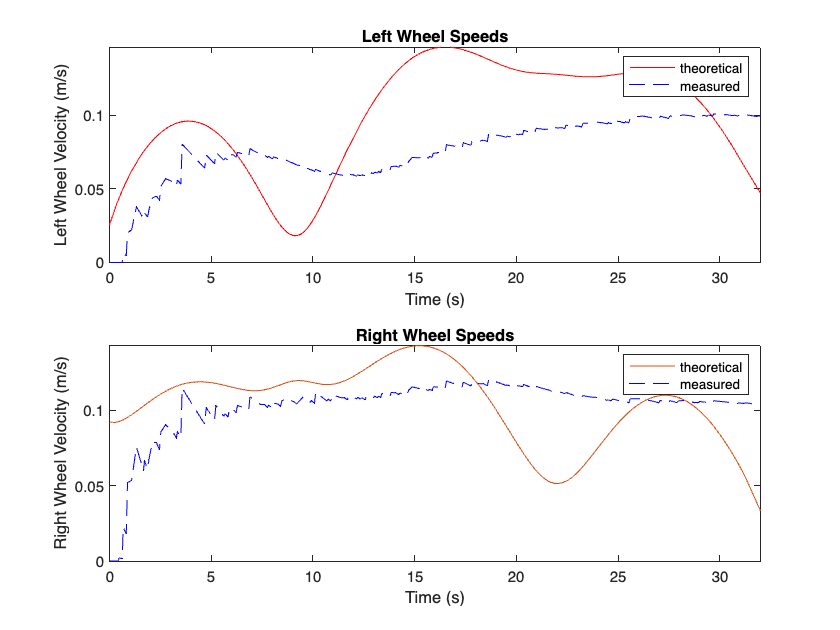

% Plot of Left and Right Wheel Speeds

%calculate left and right wheel velocities
vleft = linvel - (Angular_Velocity * (0.245 / 2));
vright = linvel + (Angular_Velocity * (0.245 / 2));

%plot left and right wheel velocities
figure("Name","Wheel Speeds")

subplot(2,1,1);
vleftplot = fplot(vleft,[0 32], '-r');
hold on
actual_left_vel = plot(encoder_data(:,1),simLeftWheelVel,'--b');
hold off
xlabel("Time (s)")
ylabel("Left Wheel Velocity (m/s)")
legend([vleftplot, actual_left_vel],["theoretical", "measured"])
title("Left Wheel Speeds")

subplot(2,1,2);
vrightplot = fplot(vright,[0 32],'Color',[0.8500 0.3250 0.0980]);
hold on
actual_right_vel = plot(encoder_data(:,1),simRightWheelVel,'--b');
hold off
xlabel("Time (s)")
ylabel("Right Wheel Velocity (m/s)")
legend([vrightplot, actual_right_vel],["theoretical", "measured"])
title("Right Wheel Speeds")